## *Battery Management System*

### Sistem Kendali Prediktif Adaptif - Final Project

#### Kelompok - 3

Anggota:

- 2206055643    Davin Nazhif Wilviadli

- 2206055662    Afif Darda Narendra

- 2206055712    Haidar Satrio Wibowo

### Kurva OCV-SOC untuk *Charging* dan *Discharging*

Dilakukan ***fitting *****polinom orde-9** kepada data OCV baterai untuk mendapatkan hubungan antara OCV dengan SOC baterai pada saat keadaan *charging *dan *discharging. *Digunakan persamaan Coulomb Counting berikut untuk mencari SOC:


$$\[
\mathrm{SoC}(t) = \mathrm{SoC}(t - 1) + \frac{I(t)}{Q_n} \, \Delta t
\]$$


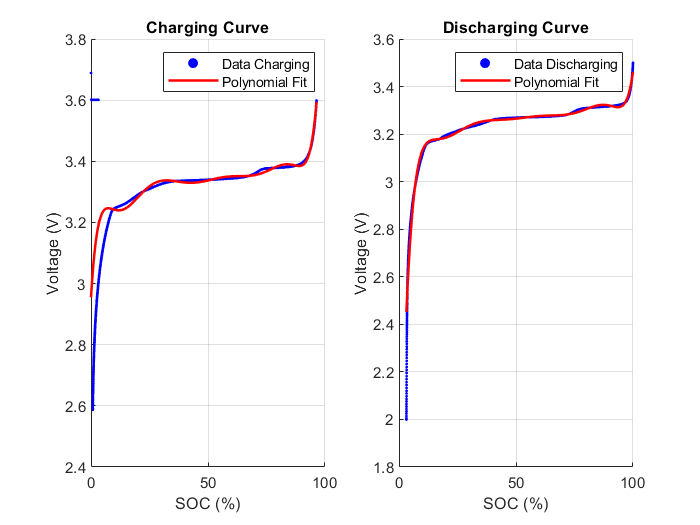

clc;
clearvars;
data = readtable('Database/OC_Current_Voltage');
Q_nominal = 1.1; % Kapasitas baterai
time = data.Step_Time;
current = data.Current_A;
voltage = data.Voltage_V;
dt = [0; diff(time)];

% Kondisi baterai dipisah ketika charging dan discharging
idx_cha = current > 0.0;
idx_dis = current < 0.0;

current_cha = current(idx_cha);
voltage_cha = voltage(idx_cha);
time_cha = time(idx_cha);
dt_cha = dt(idx_cha);

current_dis = current(idx_dis);
voltage_dis = voltage(idx_dis);
time_dis = time(idx_dis);
dt_dis = dt(idx_dis);

% Asumsi kondisi awal baterai saat charging dan discharging
soc_cha_init = 0; 
soc_dis_init = 100;

soc_cha = coulomb_counting(current_cha, time_cha, Q_nominal, soc_cha_init);   
soc_dis = coulomb_counting(current_dis, time_dis, Q_nominal, soc_dis_init); 

soc_dis_norm = soc_dis / 100;
p_dis = polyfit(soc_dis_norm, voltage_dis, 9);
soc_dis_fit = linspace(min(soc_dis_norm), max(soc_dis_norm), 200);
voltage_dis_fit = polyval(p_dis, soc_dis_fit);

soc_cha_norm = soc_cha / 100;
p_cha = polyfit(soc_cha_norm, voltage_cha, 9);
soc_cha_fit = linspace(min(soc_cha_norm), max(soc_cha_norm), 200);
voltage_cha_fit = polyval(p_cha, soc_cha_fit);

figure;

% --- Charging Curve ---
subplot(1,2,1);
scatter(soc_cha, voltage_cha, 3, 'b', 'filled', 'DisplayName', 'Data Charging');  % ukuran 10, biru, tanpa garis
hold on;
plot(soc_cha_fit*100, voltage_cha_fit, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Polynomial Fit');
xlabel('SOC (%)'); ylabel('Voltage (V)');
title('Charging Curve');
legend show; grid on;

% --- Discharging Curve ---
subplot(1,2,2);
scatter(soc_dis, voltage_dis, 3, 'b', 'filled', 'DisplayName', 'Data Discharging');
hold on;
plot(soc_dis_fit*100, voltage_dis_fit, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Polynomial Fit');
xlabel('SOC (%)'); ylabel('Voltage (V)');
title('Discharging Curve');
legend show; grid on;

Didapat persamaan polynom orde 9 berikut,


$$\begin{array}{l}
U_{{\textrm{ocv}}_{\textrm{Cha}} } =3813{\cdot \textrm{SOC}}^9 -16906{\cdot \textrm{SOC}}^8 +31678{\cdot \textrm{SOC}}^7 -32618{\cdot \textrm{SOC}}^6 +20076{\cdot \textrm{SOC}}^5 \\
-7522{\cdot \textrm{SOC}}^4 +1671{\cdot \textrm{SOC}}^3 -205{\cdot \textrm{SOC}}^2 +12\cdot \textrm{SOC}+3
\end{array}$$



$$\begin{array}{l}
U_{{\textrm{ocv}}_{\textrm{Dis}} } =3279{\cdot \textrm{SOC}}^9 -15807{\cdot \textrm{SOC}}^8 +32591{\cdot \textrm{SOC}}^7 -37545{\cdot \textrm{SOC}}^6 +26475{\cdot \textrm{SOC}}^5 \\
-11764{\cdot \textrm{SOC}}^4 +3265{\cdot \textrm{SOC}}^3 -541{\cdot \textrm{SOC}}^2 +49\cdot \textrm{SOC}+1
\end{array}$$


### Mapping nilai $U_{\textrm{OCV}}$ dari data DST berdasarkan polinom OCV-SOC

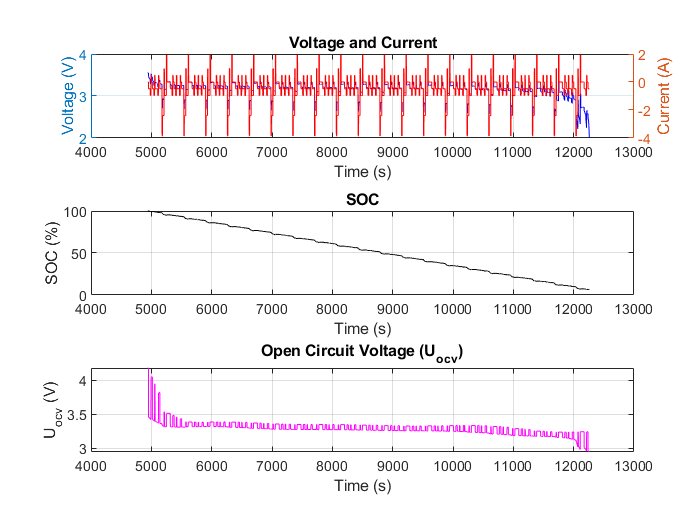

data_dst = readtable('Database/DST.csv');
time_dst = data_dst{:,1};

figure;
num_cols = width(data_dst);

% Ambil data arus dan tegangan dari data DST
current_dst = data_dst.Current_A;
voltage_dst = data_dst.Voltage_V;
dt_dst = [0; diff(time_dst)];

% Hitung SOC dari coulomb counting
soc_dst_init = 100; 
soc_dst = coulomb_counting(current_dst, time_dst, Q_nominal, soc_dst_init);

% Hitung Uoc dari fungsi polinomial yang sesuai arah arus
uoc_dst = zeros(size(soc_dst));
for k = 1:length(soc_dst)
    if current_dst(k) >= 0
        uoc_dst(k) = polyval(p_cha, soc_dst(k)/100); % fungsi charge
    else
        uoc_dst(k) = polyval(p_dis, soc_dst(k)/100); % fungsi discharge
    end
end

figure;

% Baris 1: Tegangan dan Arus terhadap waktu
subplot(3,1,1);
yyaxis left;
plot(time_dst, voltage_dst, 'b');
ylabel('Voltage (V)');
yyaxis right;
plot(time_dst, current_dst, 'r');
ylabel('Current (A)');
xlabel('Time (s)');
title('Voltage and Current');
grid on;

% Baris 2: SOC terhadap waktu
subplot(3,1,2);
plot(time_dst, soc_dst, 'k');
ylabel('SOC (%)');
xlabel('Time (s)');
title('SOC');
grid on;

% Baris 3: Uocv terhadap waktu
subplot(3,1,3);
plot(time_dst, uoc_dst, 'm');
ylabel('U_{ocv} (V)');
xlabel('Time (s)');
title('Open Circuit Voltage (U_{ocv})');
grid on;

### Algoritma Adaptive Forgetting Factor Recursive Least Square (AFFRLS) + Levenberg-Marquadt untuk estimasi parameter RC Rangkaian Orde-2

#### Penurunan Model

 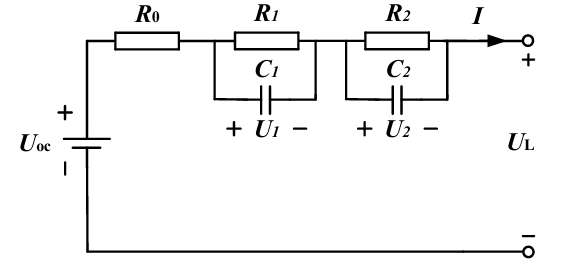

Dari rangkaian di atas didapat persamaan fungsi alih dengan $E\left(s\right)=U_L \left(s\right)-U_{\textrm{ocv}} \left(s\right)$ sebagai keluaran dan $I\left(s\right)$ sebagai masukan,


$$\[
G(s) = \frac{E(s)}{I(s)} = -\frac{R_0 s^2 + \frac{R_0 R_1 C_1 + R_0 R_2 C_2 + R_2 R_1 C_1 + R_1 R_2 C_2}{R_1 C_1 R_2 C_2} s + \frac{R_0 + R_1 + R_2}{R_1 C_1 R_2 C_2}}{s^2 + \frac{R_1 C_1 + R_2 C_2}{R_1 C_1 R_2 C_2} s + \frac{1}{R_1 C_1 R_2 C_2}}
\]
$$


Persamaan didiskritisasi menggunakan transformasi bilinear $\[
s = \frac{2}{T} \cdot \frac{1 - z^{-1}}{1 + z^{-1}}
\]
$.


$$\[
G(z^{-1}) = \frac{E(k)}{I(k)} = \frac{\theta_3 + \theta_4 z^{-1} + \theta_5 z^{-2}}{1 - \theta_1 z^{-1} - \theta_2 z^{-2}}
\]$$



$$\[
\left\{
\begin{array}{l}
\theta_1 = \frac{2T^2 - 8 R_1 C_1 R_2 C_2}{-T^2 - 2T(R_1 C_1 + R_2 C_2) - 4 R_1 C_1 R_2 C_2} \\[1em]
\theta_2 = \frac{T^2 - 2T(R_1 C_1 + R_2 C_2) + 4 R_1 C_1 R_2 C_2}{-T^2 - 2T(R_1 C_1 + R_2 C_2) - 4 R_1 C_1 R_2 C_2} \\[1em]
\theta_3 = \frac{T^2(R_0 + R_1 + R_2) + 2T(R_0 R_1 C_1 + R_0 R_2 C_2 + R_1 R_2 C_2 + R_2 R_1 C_1) + 4 R_0 R_1 C_1 R_2 C_2}{-T^2 - 2T(R_1 C_1 + R_2 C_2) - 4 R_1 C_1 R_2 C_2} \\[1em]
\theta_4 = \frac{2T^2(R_0 + R_1 + R_2) - 8 R_0 R_1 C_1 R_2 C_2}{-T^2 - 2T(R_1 C_1 + R_2 C_2) - 4 R_1 C_1 R_2 C_2} \\[1em]
\theta_5 = \frac{T^2(R_0 + R_1 + R_2) - 2T(R_0 R_1 C_1 + R_0 R_2 C_2 + R_1 R_2 C_2 + R_2 R_1 C_1) + 4 R_0 R_1 C_1 R_2 C_2}{-T^2 - 2T(R_1 C_1 + R_2 C_2) - 4 R_1 C_1 R_2 C_2}
\end{array}
\right.
\]$$


#### Metode FFRLS

Didapat persamaan rekursif,


$$\[
E(k) = \theta_1 E(k - 1) + \theta_2 E(k - 2) + \theta_3 I(k) + \theta_4 I(k - 1) + \theta_5 I(k - 2) + e(k)
\]
$$


Persamaan ini dapat diekspresikan dengan persamaan berikut untuk diiterasikan meggunakan AFFRLS,


$$\[
\theta' = \left( \varphi^T \varphi \right)^{-1} \varphi^T E
\]$$


Dimana,


$$$\theta = [\theta_1, \theta_2, \theta_3, \theta_4, \theta_5]^T$$$



$$% Langsung salin ke Live Script:
$\varphi = \left[
\begin{array}{ccccc}
E(k\!-\!1), & E(k\!-\!2), & I(k), & I(k\!-\!1), & I(k\!-\!2) \\
E(k\!-\!2), & E(k\!-\!3), & I(k\!-\!1), & I(k\!-\!2), & I(k\!-\!3) \\
\vdots, & \vdots, & \vdots, & \vdots, & \vdots \\
E(k\!-\!m\!-\!1), & E(k\!-\!m\!-\!2), & I(k\!-\!m), & I(k\!-\!m\!-\!1), & I(k\!-\!m\!-\!2)
\end{array}
\right]$$$



$$$E = [E(k),\ E(k\!-\!1),\ \ldots,\ E(k\!-\!m)]^T$
$$


#### *Adaptive *Forgeting Factor

$\lambda$ di-*update *setiap iterasi dengan persamaan berikut,


$$$\lambda(k) = \lambda_{\min} + (1 - \lambda_{\min}) \cdot h^{\varepsilon(k)}$
$$



$$$\varepsilon(k) = \mathrm{round} \left( \left( \frac{e(k)}{e_{\mathrm{base}}} \right)^2 \right)$
$$


% Hitung error E(k) = Vt - Uoc
E = voltage_dst - uoc_dst;
N = length(E);

% Inisialisasi regresor Phi dan target E(k)
Phi = zeros(N, 5);   % [E(k-1), E(k-2), I(k), I(k-1), I(k-2)]
E_target = zeros(N, 1);  % Y(k) = E(k)

for k = 1:N
    if k >= 2
        E_k_1 = E(k-1); I_k_1 = current_dst(k-1);
    else
        E_k_1 = 0; I_k_1 = 0;
    end

    if k >= 3
        E_k_2 = E(k-2); I_k_2 = current_dst(k-2);
    else
        E_k_2 = 0; I_k_2 = 0;
    end

    I_k = current_dst(k);

    Phi(k, :) = [E_k_1, E_k_2, I_k, I_k_1, I_k_2];
    E_target(k) = E(k); 
end

% Inisialisasi awal
lambda_min = 0.98;
h = 0.9;
e_base = 0.05;
T = mean(diff(time_dst));
n_param = 5;
N = size(Phi,1);

theta = zeros(n_param, N);
theta(:,1) = zeros(n_param, 1);
P = eye(n_param);
e_all = zeros(N,1);
lambda_all = zeros(N,1);
K_all = zeros(n_param, N);
y_hat_all = zeros(N, 1);

lambda = lambda_min + (1 - lambda_min) * h^0;

#### Algoritma Levenberg-Marquadt

Ketika AFFRLS berjalan, algoritma Levenberg-Marquadt juga dijalankan untuk mencari nilai parameter RC setiap waktu ke-$N$. Algoritma ini digunakan untuk menyelesaikan 5 persamaan nonlinear pencarian akar ($\theta$)

% --- Parameter LM ---%
params_init = [0.001, 0.2, 0.3, 20, 50]; % Cek kisaran yang kira-kira mungkin
lb = [1e-3, 1e-7, 1e-7, 10, 10];
ub = [10,10, 10, 2e5, 2e5];
mu_init = 1e4;       % damping LM
max_iter = 50;        % iterasi maksimum LM per titik
tol = 1e-6;           % toleransi konvergensi
delta = 1e-6;         % langkah Jacobian numerik

% --- Untuk hasil tracking ---
RC_tracking = nan(N, 5); % hasil LM tiap sample
err_tracking = nan(N, 1); % error fitting LM tiap sample

%==========Loop Theta dan Parameter RC menggunakan LM ===========%
for k = 1:N
    phi_k = Phi(k,:)';
    E_k = E_target(k);
    y_hat = theta(:,k)' * phi_k;
    error_k = E_k - y_hat;

    K = P * phi_k / (lambda + phi_k' * P * phi_k);

    if k < N
        theta(:,k+1) = theta(:,k) + K * error_k;
    end

    P = (1/lambda) * (P - K * phi_k' * P);

    % Simpan variabel iteratif
    e_all(k) = error_k;
    lambda_all(k) = lambda;
    K_all(:,k) = K;
    y_hat_all(k) = y_hat;

    % Update lambda sesuai paper
    epsilon_k = round((error_k / e_base)^2);
    lambda = lambda_min + (1 - lambda_min) * h^epsilon_k;

    % --- LM Start (untuk waktu k) ---
    theta_exp = theta(:,k);   
    params = params_init;
    mu = mu_init;

    for iter = 1:max_iter
        theta_model = rc2theta(params, T);
        err = theta_model - theta_exp;

        % Hitung Jacobian
        J = zeros(5,5);
        for j = 1:5
            params_temp = params;
            params_temp(j) = params_temp(j) + delta;
            theta_temp = rc2theta(params_temp, T);
            J(:,j) = (theta_temp - theta_model) / delta;
        end

        % LM update
        H = J'*J + mu*eye(5);         % Hessian semu
        dp = H \ (J'*err);            % langkah update (delta param)

        params_new = params - dp';     % update param
        % Boundary check:
        params_new = max(params_new, lb);
        params_new = min(params_new, ub);

        theta_new = rc2theta(params_new, T);
        err_new = theta_new - theta_exp;

        if norm(err_new) < norm(err)
            params = params_new;
            mu = mu / 10;
            if norm(err - err_new) < tol
                break;  % stop iterasi jika sudah cukup konvergen
            end
        else
            mu = mu * 10;
        end

    end
    % ---- Di sini tambahkan penyimpanan hasil params ke RC_tracking ----
    RC_tracking(k,:) = params;
    err_tracking(k) = norm(rc2theta(params, T) - theta_exp);

end

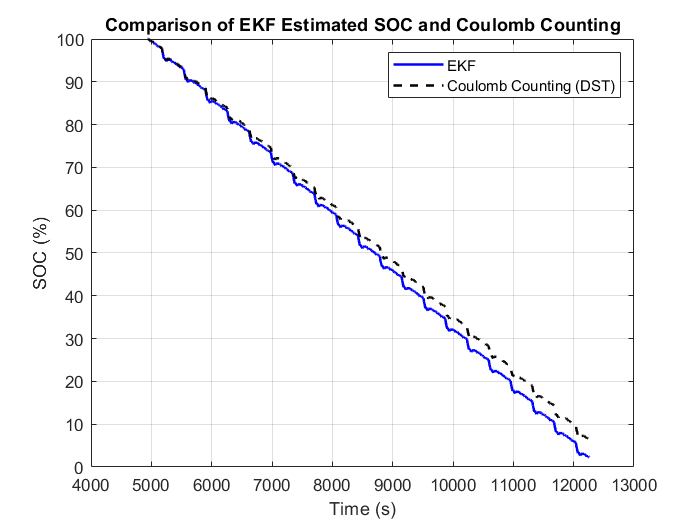

% ======= INPUT DATA =======
Ut = voltage_dst';             % Tegangan terminal (V)
I = current_dst';              % Arus (A), positif saat discharge
dt = ones(1, length(time_dst)) * 5; dt(end+1) = dt(end);  % Waktu antar sampel (s)

% Ambil parameter RC tetap (misal dari akhir RC_tracking)
R0 = RC_tracking(:,1);
R1 = RC_tracking(:,2);
R2 = RC_tracking(:,3);
C1 = RC_tracking(:,4);
C2 = RC_tracking(:,5);

% ======= INISIALISASI =======
Cn = 1.1;            % Kapasitas baterai (Ah)
N = length(I);
xHat = zeros(3,N);   % [U1; U2; SOC]
xHat(:,1) = [0; 0; 100];  % SOC awal = 100%
P = diag([0, 0, 0]);     % cukup konservatif
Q = diag([0, 0, 0]);  % Proses noise
R_kalman = 1e-3;               % Pengukuran noise

% ======= LOOP EKF =======
for k = 2:N
    curR0 = R0(k);
    curR1 = R1(k);
    curR2 = R2(k);
    curC1 = C1(k);
    curC2 = C2(k);

    tau1 = curR1 * curC1;
    tau2 = curR2 * curC2;

    A = diag([exp(-dt(k-1)/tau1), exp(-dt(k-1)/tau2), 1]);
    B = [
        curR1 * (1 - exp(-dt(k-1)/tau1));
        curR2 * (1 - exp(-dt(k-1)/tau2));
        dt(k-1)/(Cn * 3600) * 21  % skala SOC 0–100
    ];

    % Prediksi
    x_pred = A * xHat(:,k-1) + B * I(k-1);
    P_pred = A * P * A' + Q;

    % Evaluasi turunan OCV (normalisasi SOC ke [0,1])
    soc_norm = x_pred(3)/100;

    if I(k) >= 0
        dUoc = polyval(polyder(p_cha), soc_norm);
    else
        dUoc = polyval(polyder(p_dis), soc_norm);
    end

    C = [-1, -1, dUoc];
    D = -curR0;

    y_pred = C * x_pred;

    % Update EKF
    K = P_pred * C' / (C * P_pred * C' + R_kalman);
    xHat(:,k) = (x_pred + K * (Ut(k) - y_pred));
    xHat(3,k) = min(max(xHat(3,k), 0), 100);  % batas SOC
    P = (eye(3) - K * C) * P_pred;
end

% ======= PLOT HASIL =======
figure;
SOC_EKF = xHat(3,:);  % hasil EKF
SOC_CC  = soc_dst;    % hasil coulomb counting

plot(time_dst, SOC_EKF, 'b-', 'LineWidth', 1.5); hold on;
plot(time_dst, SOC_CC,  'k--', 'LineWidth', 1.5);  % garis putus-putus untuk SOC DST

xlabel('Time (s)');
ylabel('SOC (%)');
title('Comparison of EKF Estimated SOC and Coulomb Counting');
legend('EKF', 'Coulomb Counting (DST)');
grid on;

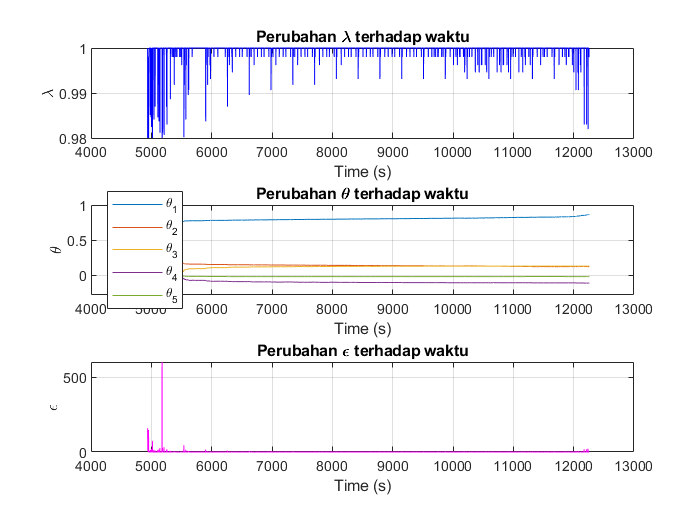

figure;

% Subplot 1: Perubahan lambda terhadap waktu
subplot(3,1,1);
plot(time_dst, lambda_all, 'b');
ylabel('\lambda');
xlabel('Time (s)');
title('Perubahan \lambda terhadap waktu');
grid on;

% Subplot 2: Perubahan theta terhadap waktu
subplot(3,1,2);
plot(time_dst, theta');
ylabel('\theta');
xlabel('Time (s)');
title('Perubahan \theta terhadap waktu');
legend({'\theta_1','\theta_2','\theta_3','\theta_4','\theta_5'}, 'Location', 'best');
grid on;

% Subplot 3: Perubahan epsilon terhadap waktu
epsilon_all = round((e_all / e_base).^2);
subplot(3,1,3);
plot(time_dst, epsilon_all, 'm');
ylabel('\epsilon');
xlabel('Time (s)');
title('Perubahan \epsilon terhadap waktu');
grid on;

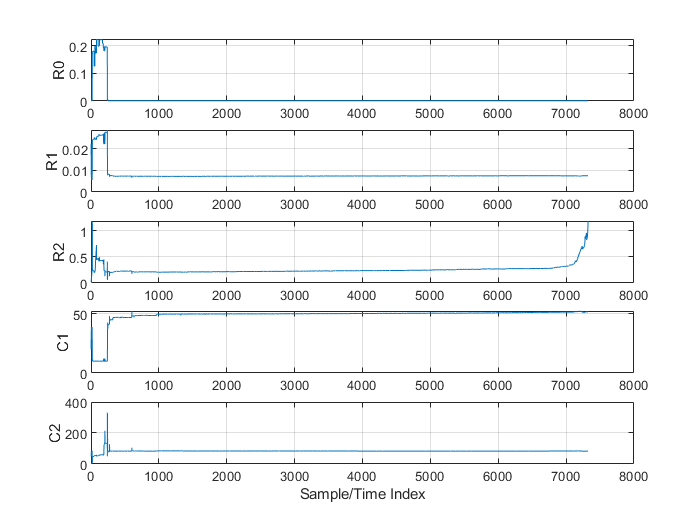


figure;
subplot(5,1,1); plot(RC_tracking(:,1)); ylabel('R0'); grid on;
subplot(5,1,2); plot(RC_tracking(:,2)); ylabel('R1'); grid on;
subplot(5,1,3); plot(RC_tracking(:,3)); ylabel('R2'); grid on;
subplot(5,1,4); plot(RC_tracking(:,4)); ylabel('C1'); grid on;
subplot(5,1,5); plot(RC_tracking(:,5)); ylabel('C2'); grid on;
xlabel('Sample/Time Index');

function soc = coulomb_counting(current, time, Q_nominal, soc_init)
    dt = [0; diff(time)];
    soc = zeros(length(current), 1);
    soc(1) = soc_init;

    for k = 2:length(current)
        delta_soc = (current(k) * dt(k)) / (Q_nominal * 3600) * 100;
        soc(k) = soc(k-1) + delta_soc;
    end

    soc = max(0, min(100, soc)); % Clamp SOC di antara 0–100%
end

%=============Persamaan (5) dari Paper================%
function theta_model = rc2theta(params, T)
    R0 = params(1); R1 = params(2); R2 = params(3);
    C1 = params(4); C2 = params(5);

    den = -T^2 - 2*T*(R1*C1 + R2*C2) - 4*R1*C1*R2*C2;
    theta1 = (2*T^2 - 8*R1*C1*R2*C2) / den;
    theta2 = (T^2 - 2*T*(R1*C1 + R2*C2) + 4*R1*C1*R2*C2) / den;
    theta3 = (T^2*(R0 + R1 + R2) + 2*T*(R0*R1*C1 + R0*R2*C2 + R2*R1*C2 + R2*R1*C1) + 4*R0*R1*C1*R2*C2) / den;
    theta4 = (2*T^2*(R0 + R1 + R2) - 8*R0*R1*C1*R2*C2) / den;
    theta5 = (T^2*(R0 + R1 + R2) - 2*T*(R0*R1*C1 + R0*R2*C2 + R1*R2*C2 + R2*R1*C1) + 4*R0*R1*C1*R2*C2) / den;

    theta_model = [theta1; theta2; theta3; theta4; theta5];
end
